# HW 5

Utkarsh Jain

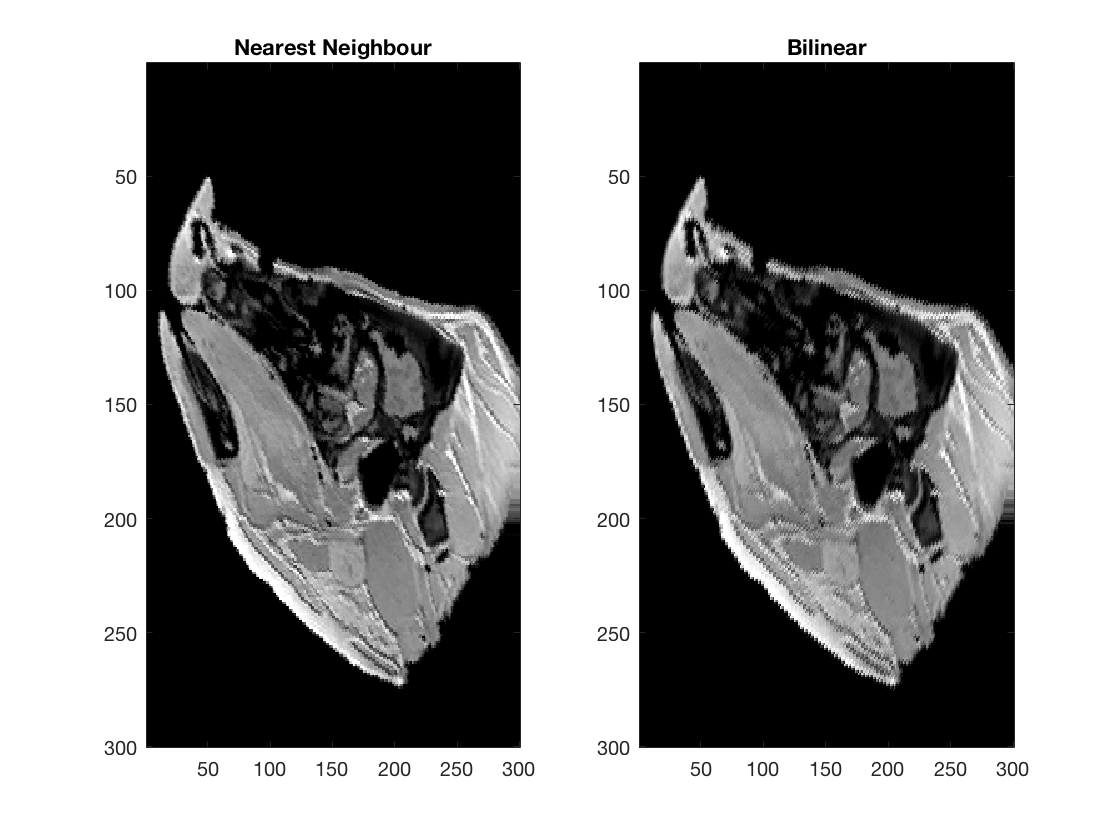

% 1)
clear;
file_path = '/Users/utkarsh/UW-Mad Courses/CS567BookStuff/LessonData/7_SpatialTransforms';
img=double(imread(sprintf('%s/PorkyPig.jpg', file_path)));

rotimg=zeros(300,300);

angle=-20;
rotmat=zeros(2,2);
rotmat(1,1)=cos(angle*pi/180);
rotmat(1,2)=-sin(angle*pi/180);
rotmat(2,1)=sin(angle*pi/180);
rotmat(2,2)=cos(angle*pi/180);

rotmat_inv=inv(rotmat);

rotimg=zeros(300,300);
oldpix=zeros(2,1);
newpix=zeros(2,1);

shift=zeros(2,1);
shift(1,1)= 150;
shift(2,1)= 150;
rho=0;

for i=1:300
    for j=1:300
        newpix(1,1)=i;
        newpix(2,1)=j;
	    oldpix=round(rotmat_inv*(newpix-shift)+shift);
        if (oldpix(1,1) > 0) & (oldpix(1,1) < 300) & (oldpix(2,1) > 0) & (oldpix(2,1) < 300)
            rho=img(oldpix(1,1),oldpix(2,1));
        end
	rotimg(i,j)=rho;
    end
end

rotimgbilinear=zeros(300,300);
rho = 0;
for i=1:300
    for j=1:300
        newpix(1,1)=i;
        newpix(2,1)=j;
	    oldpix=rotmat_inv*(newpix-shift)+shift;
        diff = rem(oldpix,1);
        if ((floor(oldpix(1,1)) > 0) & (floor(oldpix(1,1)) < 300) & (floor(oldpix(2,1)) > 0) & (floor(oldpix(2,1)) < 300))
            leftvec = [1-diff(1,1);diff(1,1)]';
            middle = [img(floor(oldpix(1,1))+1,floor(oldpix(2,1))),img(floor(oldpix(1,1))+1,...
              floor(oldpix(2,1))+1);img(floor(oldpix(1,1)),floor(oldpix(2,1))),img(floor(oldpix(1,1)),floor(oldpix(2,1))+1)];
            rightvec = [1-diff(2,1);diff(2,1)];
            rho=leftvec*middle*rightvec;
        end
	rotimgbilinear(i,j)=rho;
    end
end


figure
colormap(gray)
subplot(1, 2, 1)
imagesc(rotimg)
title('Nearest Neighbour')
subplot(1,2,2)
imagesc(rotimgbilinear)
title('Bilinear')

%2)

clear;
file_path =  '/Users/utkarsh/UW-Mad Courses/CS567BookStuff/LessonData/9_Registration';
img= double(imread(sprintf('%s/CT.jpg', file_path)));
otherimg=double(imread(sprintf('%s/T1.jpg', file_path)));

jhist=zeros(1,256);
for i=1:388
    for j=1:388
        jhist(1,img(i,j)+1) = jhist(1,img(i,j)+1) + 1;
    end
end

HCT = 0;
for i=1:256
    if jhist(1,i)~=0
        p = jhist(1,i)./(size(img,1)*size(img,2));
        HCT = HCT + -1*p*log(p);
    end
end

HCT

HCT = 2.8000


jhist=zeros(1,256);
for i=1:388
    for j=1:388
        jhist(1,otherimg(i,j)+1) = jhist(1,otherimg(i,j)+1) + 1;
    end
end

HT1 = 0;
for i=1:256
    if jhist(1,i)~=0
        p = jhist(1,i)./(size(otherimg,1)*size(otherimg,2));
        HT1 = HT1 + -1*p*log(p);
    end
end

HT1

HT1 = 2.0022

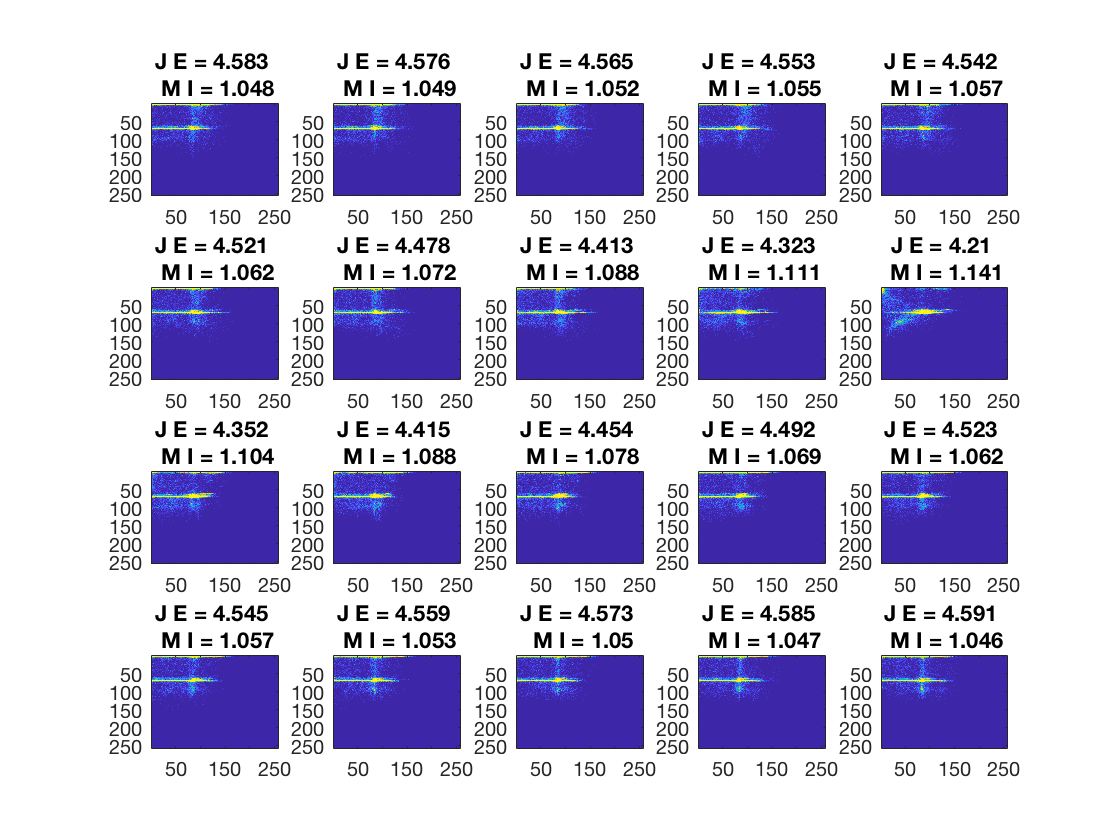

jhist=zeros(1,256);
figure
for a=-9:10
    rotimg=zeros(388,388);
    angle=a*10;
    rotmat=zeros(2,2);
    rotmat(1,1)=cos(angle*pi/180);
    rotmat(1,2)=-sin(angle*pi/180);
    rotmat(2,1)=sin(angle*pi/180);
    rotmat(2,2)=cos(angle*pi/180);
    invrotmat=transpose(rotmat);
    oldpix=zeros(2,1);
    newpix=zeros(2,1);
    shift=transpose([194,194]);
    for i=1:388
        for j=1:388
            newpix(1,1)=i;
            newpix(2,1)=j;
            oldpix=round((invrotmat*(newpix-shift))+shift);
            if (oldpix(1,1) > 0) & (oldpix(1,1) < 388) & (oldpix(2,1) > 0) & (oldpix(2,1) < 388)
                rotimg(i,j)=otherimg(oldpix(1,1),oldpix(2,1));
            end
        end
    end
    jhist=zeros(256,256);
    for i=1:388
        for j=1:388
            rho1=img(i,j)+1;
            rho2=rotimg(i,j)+1;
            jhist(rho1,rho2)=jhist(rho1,rho2)+1;
        end
    end
    Hjoint = 0;
    for i=1:256
        for j=1:256
            if jhist(i,j)~=0
                p = jhist(i,j)./(size(img,1)*size(img,2));
                Hjoint = Hjoint + -1*p*log(p);
            end
        end
    end
    mutinfo = (HCT+HT1)./Hjoint;
    m = 4;
    s = 4;
    jhist = 63*1./(1+exp(-1*(jhist-m)/s));
    subplot(4, 5, a+10)
    imagesc(jhist)
    title(sprintf('J E = %.4g \n M I = %.4g', Hjoint,mutinfo));
end

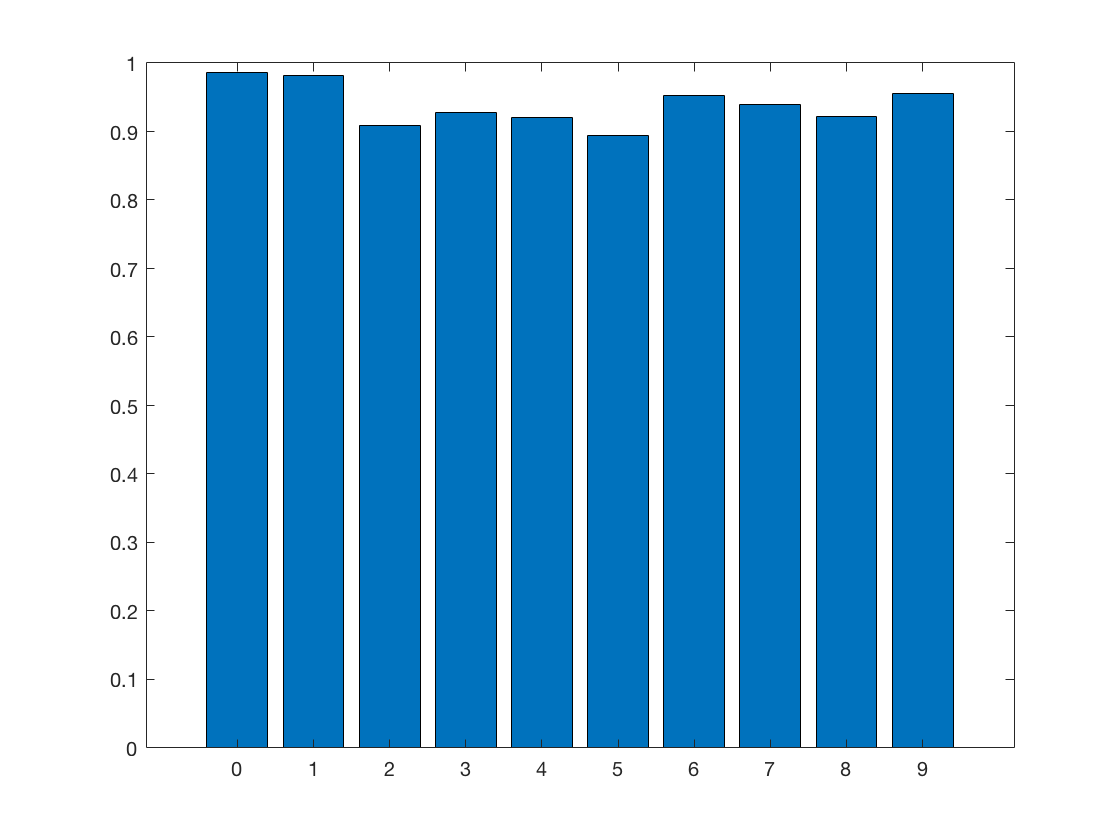

%3)

train = load('/Users/utkarsh/Downloads/train.txt', '-ascii');
test = load('/Users/utkarsh/Downloads/test.txt', '-ascii');

labels_train = train(:,1);
labels_test = test(:,1);

feat_train = train(:,2:end);
feat_test = test(:,2:end);

k = 5;

pred = zeros(size(test,1),1);

for i=1:size(test,1)
    test_temp = test(i,2:end)';
    dist = zeros(1,size(train,1));
    for j = 1:size(train,1)
        train_temp = train(j,2:end)';
        dist(1,j) = sqrt(sum((test_temp - train_temp).^2));
    end
    [~, ord] = sort(dist);
    knn=labels_train(ord(1:k));
    vals = zeros(1,10);
    for l=0:9
        vals(l+1) = mean(knn == l);
    end
    [vals, ord] = sort(vals,'descend');
    sameinds = find(vals == vals(1));
    pred(i) = ord(randperm(length(sameinds),1))-1;
end

preds = zeros(1,10);
for i=0:9
    preds(i+1) = sum(pred==labels_test & labels_test==i)/sum(labels_test==i);
end

figure;
bar(0:9,preds);